# **Identification and Estimation**

# **Exam December 14**

# **9 am to 11 am**

**Open book, open internet, no communication with human beeing allowed**

This exam is a "matlab live script" : a format that mix text and executable code. Each "section" can be run separately (Tab LIVE EDITOR/Run Section). The outputs is shown on right.

You will be asked:

- to complete, modify and comment matlab code. (into "code" sections)

- to answer literal questions (into "text" sections)

The aim of the exam is to compare two estimation algorithms for the same problem.

A discrete process is driven by the linear discrete equation:


$$\begin{array}{l}
x\left(t+1\right)=0\ldotp 999*x\left(t\right)+e\left(t\right)+u\left(t\right)\\
y\left(t\right)=x\left(t\right)+v\left(t\right)
\end{array}$$


where :

- $x\left(t\right)$ is the internal state

- $e\left(t\right)$ is a control input

- $u\left(t\right)$ is a zero mean random noise (gaussian distribution, known variance Q=0.05)

- $v\left(t\right)$ correspond to the error of the sensor. This error is only known to be +/-1

In the following code we simulate the output when the input is a pseudo random binary signal. The "real" state x(t) is simulated and will be estimated in the next questions. (This section must be executed before the next ones).

close all;
T=500; %number of samples
x = zeros(1,T);
y =zeros(1,T);
e = 0.1*idinput(T,'prbs');% prbs signal

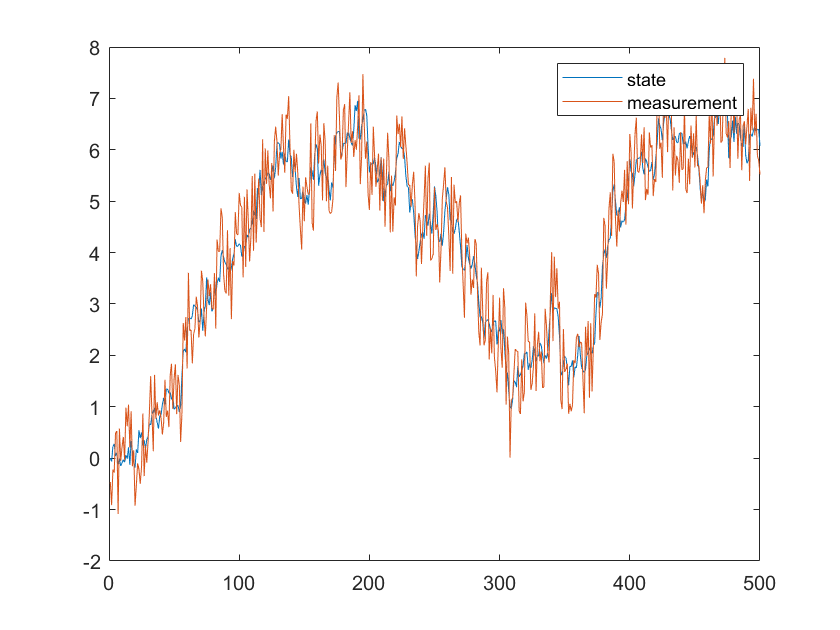

Q=0.05; %variance of the additive state noise
load noise;

%Simulation of the "real" signals
for t=2:T
    %simulate output and internal state
    x(t) = 0.999*x(t-1) + e(t) + sqrt(Q)*randn(1);
end
y = x+noise;
plot(1:T,x,1:T,y);legend('state','measurement');

## **I. exercice 1 : Kalman filtering (7 points)**

We want to compute the estimate xe(t) of the state x(t) using only the known input e(t) and measured output y(t).

### Question 1

Complete and modify the following code in order to achieve this filtering.

**Answer**: the additive noise is not clearly defined on the text. Let's plot the hisotgram of this additive signal:

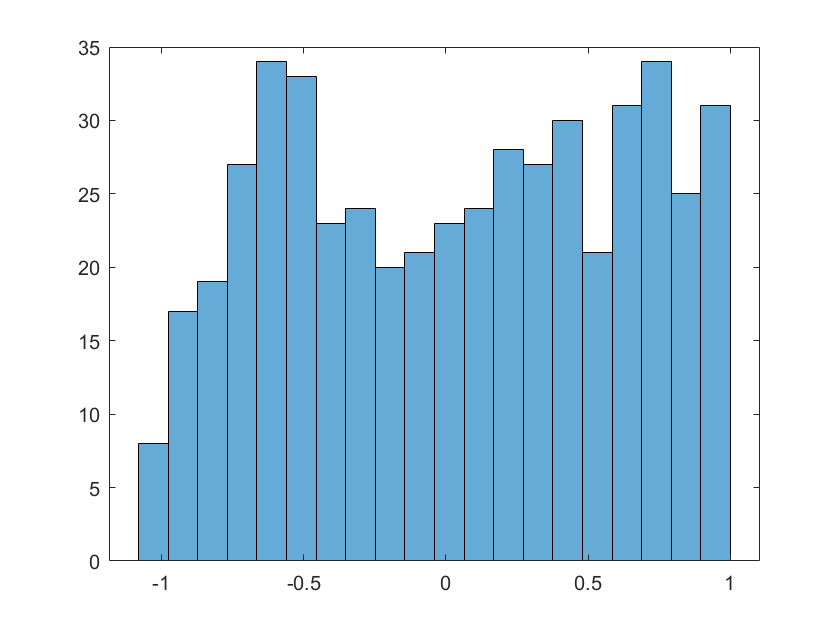

histogram(noise,20)

We can see that this additive noise has a distribution which is far from being Gaussian. More like a uniform distribution. 

For the coding a Kalman filter we must assume this additive noise to be Gaussian. Let's compute the variance:

R = var(noise)

R = 0.3388

We take this value for R in the code.

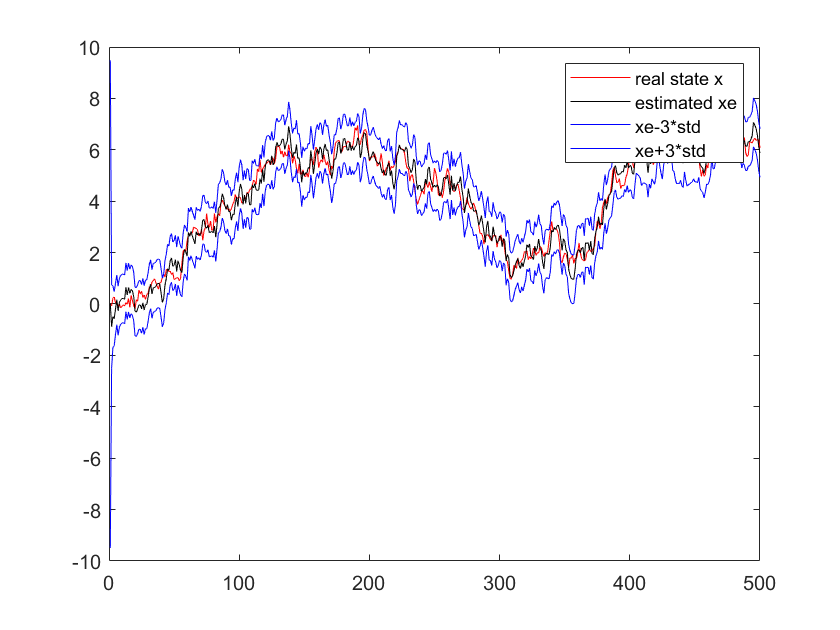


P(1)=10; %initial value of the filter covariance error (Kalman filter)
R=0.3;%variance of the additive filter measurement noise
xe=0; %inial value of the filter estimated state 1
ypred=0;

for t=2:T
    %estimate the state x(t)
    %your code begins here
    %predict
    xe(t) = 0.999*xe(t-1) + e(t) + sqrt(Q)*randn(1,1);
    A=0.999;
    P(t)=A*P(t-1)*A'+Q;
    %Update
    ypred(t)=xe(t);
    C=1;
    K=P(t)*C'*inv(C*P(t)*C' + R);
    P(t)=P(t)-K*C*P(t);
    xe(t)=xe(t)+K*(y(t)-ypred(t));
    %end of your code
end
plot(1:T,x,'r',1:T,xe,'k',1:T,xe-3*sqrt(P),'b',1:T,xe+3*sqrt(P),'b');
legend('real state x','estimated xe','xe-3*std','xe+3*std');

x_k = xe;

### Question 2

Discuss the validity and the precision of your estimation

**Answer**: ther estimate is based on the asumption that the additive perturbation is a gaussian white noise. The result is the best we can obtain with a Kalman filter. We exhibit the interval corresponding to three standard deviations, corresponding to 99% of confidence with a Gaussian assumption.

## **II. exercice 2 : Particle filtering (7 points)**

We want to compute the estimate xe(t) of the state x(t) using only the known input e(t) and measured output y(t).

The state is now estimated with a particle filter.

### Question 1

Complete and modify the following code in order to achieve this filtering.

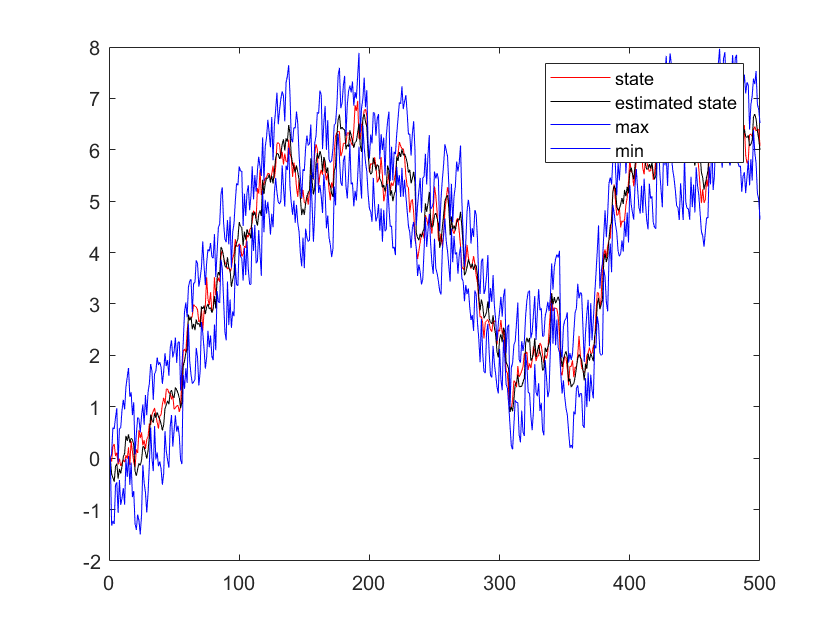


initVar = [0.1]; % Initial variance of the state.
N = 1000;         % Number of Particles
xp = zeros(T,N); % N particles, T samples
q = zeros(T,N); % N weights, T samples
xp(1,:) = sqrt(initVar)*randn(1,N); % Initial particles
q(1,:) = 1/N*ones(1,N); % Initial weights

for t=2:T
    %Predict
    xp(t,:) = 0.999*xp(t-1,:) + e(t) + sqrt(Q)*randn(1,N);
    %Measurement error
    err = y(t)-xp(t,:);
    %Probability of measurement
    p = ones(1,N);
    for k = 1:N
        if abs(err(k))>1 p(k)=0;
        end
    end
    %Importance weight
    for k = 1:N
        q(t,k) = q(t-1,k)*p(k);
    end
    W = sum(q(t,:));
    q(t,:) = q(t,:)/W;
    %Resampling
    [~, index] = histc(sort(rand(N,1)), cumsum(q(t,:)));
    xp(t,:) = xp(t, index+1);
    q(t,:) = 1/N*ones(1,N);
    %Mean xe of x
    xe(t) = mean(xp(t,:));
    %Variance ve of x
    ve(t) = var(xp(t,:));
    %Standard deviation se of x
    se(t) = sqrt(ve(t));
    %Max xM of x
    maxe(t) = max(xp(t,:));
    %Min xm of x
    mine(t) = min(xp(t,:));
end

% plot(1:T,x,'r',1:T,xp(:,1:1:end),'k'); %plot 
% legend('particles');
plot(1:T,x,'r',1:T,xe,'k',1:T,maxe,'b',1:T,mine,'b');
legend('state','estimated state','max','min');

x_pf = xe;

**Comment** : full points if you take into account the uniform distribution of the aditive noise

### Question 2

Discuss the validity and the precision of your estimation

**Answer** : we have a precise model of the additive noise.The additive noise being uniformly distributed in the range [-1 1] we exhibt the 100% confidence interval withj the max and the min of the remaining particles after resampling.

## **III. Discussion (6 points)**

Which is the best estimate? How can we compare the performances?

**Answer** : the best estimator is expected to be the Particle Filter since it is based on a more accurate model of the addive noise. We can compare the performance by computing the mean square error of both filters :

err_k =x-x_k;
mse_k = (err_k*err_k')/T

mse_k = 0.1377

err_pf =x-x_pf;
mse_pf = (err_pf*err_pf')/T

mse_pf = 0.0790